Declaring and defining requirements

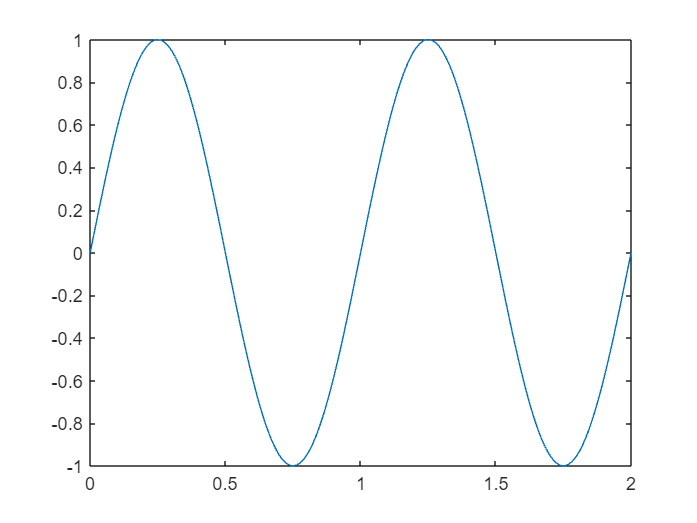

fs=1000;
T=1/fs;
t=0:T:2;
fm=1;
fc=10;
m=sin(2*pi*fm*t);
c=sin(2*pi*fc*t);
plot(t,m);

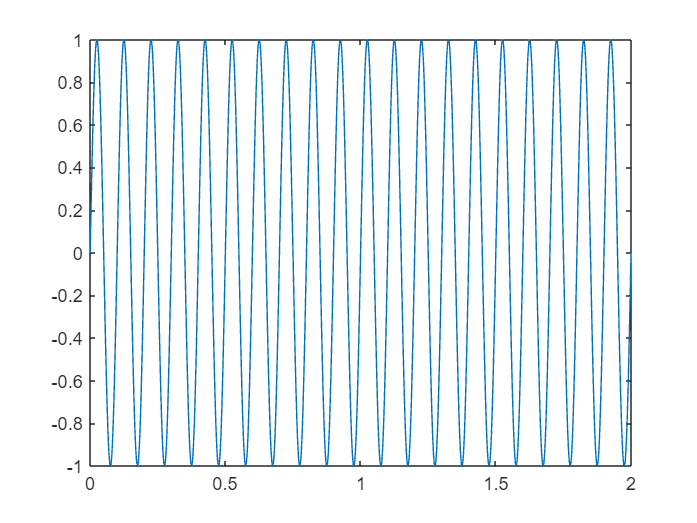

plot(t,c);

Amplitude Modulation (u=1)

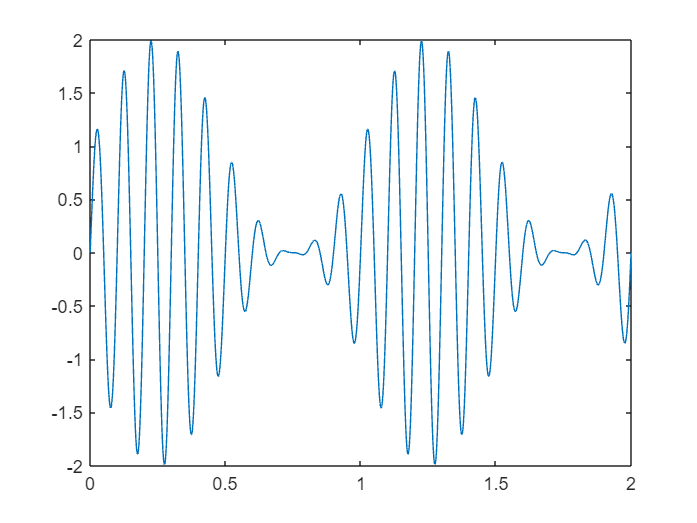

Am=(1+m).*c;
plot(t,Am)

Frequency domain Representation

N=length(Am)

N = 2001

x=fftshift(fft(Am)/N)

x =   -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i


t=linspace(-fs/2,fs/2,N)

t =  -500.0000 -499.5000 -499.0000 -498.5000 -498.0000 -497.5000 -497.0000 -496.5000 -496.0000 -495.5000 -495.0000 -494.5000 -494.0000 -493.5000 -493.0000 -492.5000 -492.0000 -491.5000 -491.0000 -490.5000 -490.0000 -489.5000 -489.0000 -488.5000 -488.0000 -487.5000 -487.0000 -486.5000 -486.0000 -485.5000 -485.0000 -484.5000 -484.0000 -483.5000 -483.0000 -482.5000 -482.0000 -481.5000 -481.0000 -480.5000 -480.0000 -479.5000 -479.0000 -478.5000 -478.0000 -477.5000 -477.0000 -476.5000 -476.0000 -475.5000


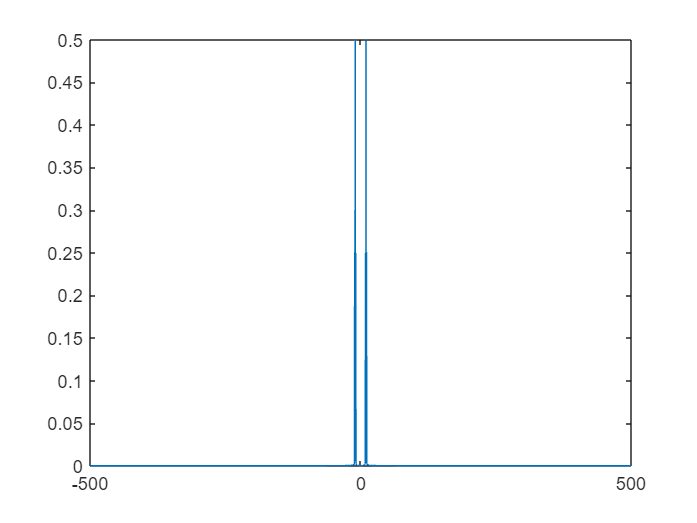

plot(t,abs(x))